**1. Considere a seguinte situação e responda às alíneas abaixo:**

Um aluno do primeiro ano de um curso de Engenharia tem todas as semanas 2 aulas Teórico-Práticas de

uma Unidade Curricular X às 9:00, às quartas e sextas.

Todos os dias que tem aulas desta UC, o aluno decide se vai à aula ou não da seguinte forma: 

    - Se tiver estado presente na aula anterior a probabilidade de ir à aula é 70%; 

    - Se faltou à anterior, a probabilidade de ir é 80%.

**(a)** Se estiver presente na aula de quarta numa determinada semana, qual a probabilidade de estar

presente na aula de quarta da semana seguinte?

Sugestão: Comece por definir a matriz de transição de estados e o vetor estado correspondentes.

T = [0.7, 0.8; % <-- Não faltar
     0.3, 0.2]; % <-- Faltar

% Queremos saber a probabilidade de estar presente na proxima quarta,
% sabendo que estivemos presentes nesta. Para isso precisamos descobrir a
% vetor estado final (k = 2) e o vetor estado incial (k = 0).
% Formula:  x(k) = (T^k)*x(0)

% Vetor estado inicial (k = 0)
x_0 = [1;  % <-- Não faltar
       0]; % <-- Faltar

% Vetor estado final (k = 2)
x_2 = (T^2)*x_0;

disp("Probabilidade de estar presente na proxima quarta: "+ x_2(1,:))

Probabilidade de estar presente na proxima quarta: 0.73


% Conta equivalente: 0.3*0.8 + 0.7*0.7 = 0.73

**(b)** Se não estiver presente na aula de quarta numa determinada semana, qual a probabilidade de estar

presente na aula de quarta da semana seguinte?

x_0 = [0;  % <-- Não faltar
       1]; % <-- Faltar

T = [0.7, 0.8; % <-- Não faltar
     0.3, 0.2]; % <-- Faltar

x_2 = (T^2)*x_0;

disp("Probabilidade de estar presente na proxima quarta: "+ x_2(1,:))

Probabilidade de estar presente na proxima quarta: 0.72


% Conta equivalente: 0.2*0.8 + 0.8*0.7 = 0.72

**(c)** Sabendo que esteve presente na primeira aula, qual a probabilidade de estar na última aula, assumindo que o semestre tem exactamente 15 semanas de aulas e não existem feriados?

x_0 = [1;  % <-- Não faltar
       0]; % <-- Faltar

% 15 semanas de aula = 30 aulas
k = 29;

T = [0.7, 0.8; % <-- Não faltar
     0.3, 0.2]; % <-- Faltar

x_29 = (T^k)*x_0;

disp("Probabilidade de estar na ultima aula: " + x_29(1, :))

Probabilidade de estar na ultima aula: 0.72727


**(d)** Represente num gráfico a probabilidade de faltar a cada uma das 30 aulas, assumindo que a probabilidade de estar presente na primeira aula é de 85%.

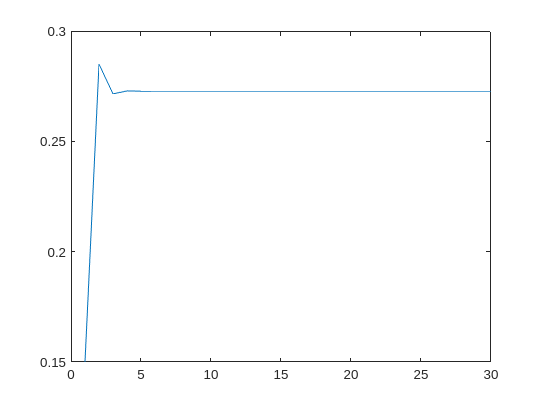

prob_faltar = zeros(30, 1);
prob_faltar(1) = 0.15;

x_0 = [0.85;  % <-- Não faltar
       0.15]; % <-- Faltar

T = [0.7, 0.8; % <-- Não faltar
     0.3, 0.2]; % <-- Faltar

for k = 1:29
    x_k = (T^k)*x_0;
    prob_faltar(k+1) = x_k(2);
end

plot(1:30, prob_faltar)

**2. Considere a seguinte “dança” de grupos: Divide-se uma turma em 3 grupos (A, B e C) no início do**

**semestre e no final de cada aula efectuam-se os seguintes movimentos:**

    • 1/3 do grupo A vai para o grupo B e outro 1/3 do grupo A vai para o grupo C;

    • 1/4 do grupo B vai para A e 1/5 de B vai para C

    • Metade do grupo C vai para o grupo B; a outra mantém-se no grupo C.

**(a)** Crie em Matlab a matriz de transição de estados que representa as trocas entre grupos.

Confirme que se trata de uma matriz estocástica.

%    A    B      C
T = [1/3, 1/4  , 0; % <-- A
     1/3, 11/20, 1/2; % <-- B
     1/3, 1/5  , 1/2]; % <-- C

if sum(T(:, 1)) == 1 && sum(T(:, 2)) == 1 && sum(T(:, 3)) == 1
    disp("É uma matriz estocástica!  =)")
else
    disp("Não é uma matriz estocástica!  =(")
end

É uma matriz estocástica!  =)


**(b)** Crie o vector relativo ao estado inicial considerando que no total temos 90 alunos, o grupo A tem

o dobro da soma dos outros dois e os grupos B e C têm o mesmo número de alunos.

x_0 = [60; % <-- A
       15; % <-- B
       15]; % <-- C

x_0 =     60
    15
    15


**(c)** Quantos elementos integrarão cada grupo no fim da aula 30 considerando como estado inicial o

definido na alínea anterior?

k = 29;

x_29 = T^k * x_0

x_29 =    16.6667
   44.4444
   28.8889



disp("Numero de alunos no grupo A: " + x_29(1))

Numero de alunos no grupo A: 16.6667


disp("Numero de alunos no grupo B: " + x_29(2))

Numero de alunos no grupo B: 44.4444


disp("Numero de alunos no grupo C: " + x_29(3))

Numero de alunos no grupo C: 28.8889


**(d)** Quantos elementos integrarão cada grupo no fim da aula 30 considerando que inicialmente se distribuiram os 90 alunos equitativamente pelos 3 grupos?

x_0 = [30; % <-- A
       30; % <-- B
       30]; % <-- C

x_29 = T^k * x_0

x_29 =    16.6667
   44.4444
   28.8889



disp("Numero de alunos no grupo A: " + x_29(1))

Numero de alunos no grupo A: 16.6667


disp("Numero de alunos no grupo B: " + x_29(2))

Numero de alunos no grupo B: 44.4444


disp("Numero de alunos no grupo C: " + x_29(3))

Numero de alunos no grupo C: 28.8889


**3. Gere aleatoriamente uma matriz de transição de estados para uma cadeia de 20 estados (identificados de 1 a 20) recorrendo à função do Matlab rand. Com base nessa matriz:**

**(a) **Confirme que a matriz de transição de estados é estocástica.

T = rand(20);

% Normalizar as colunas para que a soma de cada coluna seja 1
for i = 1:20
    T(:, i) = T(:, i) / 20;
end

% Verificar se a matriz é estocástica
is_stochastic = 0;
for i=1:20
    if sum(T(:, i)) - 1 < 1e-10 % Permitir erro numérico pequeno
        is_stochastic = is_stochastic + 1;
    end
end

if is_stochastic == 20
    disp("Matriz é estocástica! =)")
else
    disp("Matriz não é estocástica! =(")
end

Matriz é estocástica! =)


**(b)** Qual a probabilidade de o sistema, começando no estado 1, estar no estado 20 após 2 transições? E após 5? E após 10? E após 100? Apresente os resultados em percentagem e com 5 casas decimais.

O que conclui?

x_0 = zeros(20, 1);
x_0(1) = 1;

% Após duas transições
x_2 = T^2 * x_0;
disp("Probabilidade de estado 20 após 2 transições: " + x_2(20, 1))

Probabilidade de estado 20 após 2 transições: 0.040669



% Após cinco transições
x_5 = T^5 * x_0;
disp("Probabilidade de estado 20 após 5 transições: " + x_5(20, 1))

Probabilidade de estado 20 após 5 transições: 0.038758



% Após 10 transições
x_10 = T^10 * x_0;
disp("Probabilidade de estado 20 após 10 transições: " + x_10(20, 1))

Probabilidade de estado 20 após 10 transições: 0.038763



% Após 100 transições
x_100 = T^100 * x_0;
disp("Probabilidade de estado 20 após 100 transições: " + x_100(20, 1))

Probabilidade de estado 20 após 100 transições: 0.038763


**Conclusão: **A probabilidade converge para o valor `0.03876`

**4. Considere o seguinte diagrama representativo de uma Cadeia de Markov:**

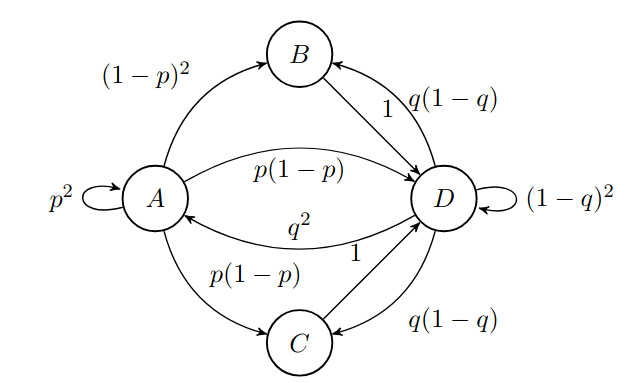

**(a)** Defina, em Matlab, a matriz de transição de estados T assumindo p = 0, 4 e q = 0, 6.

p = 0.4;
q = 0.6;

%    A        B  C  D
T = [p^2     , 0, 0, q^2 % <-- A
     (1-p)^2 , 0, 0, q-q^2 % <-- B
     p-p^2   , 0, 0, q-q^2 % <-- C
     p-p^2   , 1, 1, (1-q)^2]; % <-- D

% Verificar se a matriz é estocástica
is_stochastic = 0;
for i=1:4
    if sum(T(:, i)) - 1 < 1e-10 % Permitir erro numérico pequeno
        is_stochastic = is_stochastic + 1;
    end
end

if is_stochastic == 4
    disp("Matriz é estocástica! =)")
else
    disp("Matriz não é estocástica! =(")
end

Matriz é estocástica! =)


**(b)** Assuma que o sistema se encontra inicialmente no estado A. Qual a probabilidade de estar em cada

estado ao fim de 5 transições? E de 10 transições? E de 100 transições? E de 200 transições?

x_0 = [1; % <-- A
       0; % <-- B
       0; % <-- C
       0] % <-- D

x_0 =      1
     0
     0
     0



% Fazer 5 transições
x_5 = T^5 * x_0

x_5 =     0.2103
    0.1824
    0.1624
    0.4448


disp("Probabilidade de estar no estado A após 5 transições: " + x_5(1, 1))

Probabilidade de estar no estado A após 5 transições: 0.21034


disp("Probabilidade de estar no estado B após 5 transições: " + x_5(2, 1))

Probabilidade de estar no estado B após 5 transições: 0.18242


disp("Probabilidade de estar no estado C após 5 transições: " + x_5(3, 1))

Probabilidade de estar no estado C após 5 transições: 0.16243


disp("Probabilidade de estar no estado D após 5 transições: " + x_5(4, 1))

Probabilidade de estar no estado D após 5 transições: 0.44481



% Fazer 10 transições
x_10 = T^10 * x_0

x_10 =     0.1979
    0.1821
    0.1583
    0.4616


disp("Probabilidade de estar no estado A após 10 transições: " + x_10(1, 1))

Probabilidade de estar no estado A após 10 transições: 0.19794


disp("Probabilidade de estar no estado B após 10 transições: " + x_10(2, 1))

Probabilidade de estar no estado B após 10 transições: 0.18208


disp("Probabilidade de estar no estado C após 10 transições: " + x_10(3, 1))

Probabilidade de estar no estado C após 10 transições: 0.15834


disp("Probabilidade de estar no estado D após 10 transições: " + x_10(4, 1))

Probabilidade de estar no estado D após 10 transições: 0.46164



% Fazer 100 transições
x_100 = T^100 * x_0

x_100 =     0.1979
    0.1821
    0.1583
    0.4617


disp("Probabilidade de estar no estado A após 100 transições: " + x_100(1, 1))

Probabilidade de estar no estado A após 100 transições: 0.19789


disp("Probabilidade de estar no estado B após 100 transições: " + x_100(2, 1))

Probabilidade de estar no estado B após 100 transições: 0.18206


disp("Probabilidade de estar no estado C após 100 transições: " + x_100(3, 1))

Probabilidade de estar no estado C após 100 transições: 0.15831


disp("Probabilidade de estar no estado D após 100 transições: " + x_100(4, 1))

Probabilidade de estar no estado D após 100 transições: 0.46174



% Fazer 200 transições
x_200 = T^200 * x_0

x_200 =     0.1979
    0.1821
    0.1583
    0.4617


disp("Probabilidade de estar no estado A após 200 transições: " + x_200(1, 1))

Probabilidade de estar no estado A após 200 transições: 0.19789


disp("Probabilidade de estar no estado B após 200 transições: " + x_200(2, 1))

Probabilidade de estar no estado B após 200 transições: 0.18206


disp("Probabilidade de estar no estado C após 200 transições: " + x_200(3, 1))

Probabilidade de estar no estado C após 200 transições: 0.15831


disp("Probabilidade de estar no estado D após 200 transições: " + x_200(4, 1))

Probabilidade de estar no estado D após 200 transições: 0.46174


**(c)** Determine as probabilidades limite de cada estado. Compare estes valores com os obtidos na alínea

anterior. O que conclui?

% (T-I)u aumentado com u1+u2
M=[T-eye(length(T));
    ones(1, length(T))];

n = zeros(length(T), 1);
n(length(T) + 1, 1) = 1;

valor_teorico = M\n

valor_teorico =     0.1979
    0.1821
    0.1583
    0.4617


**6. Considere a cadeia de Markov com o diagrama de transição de estados seguinte:**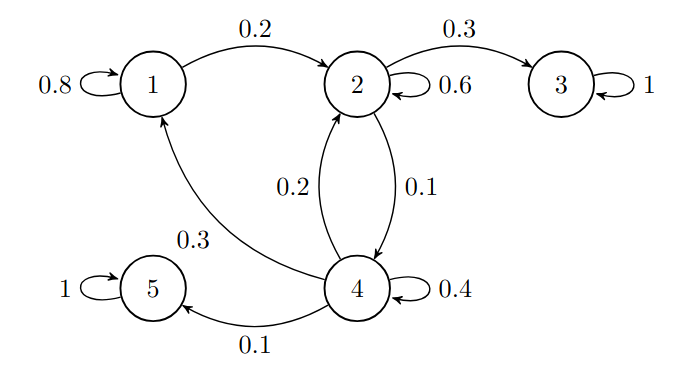

**(a)** Defina em Matlab a matriz de transição de estados T , com Tij sendo a probabilidade de ir do estado j para o estado i num único passo.

%    1  2  3  4  5 
T = [8  0  0  3  0; % <-- 1
     2  6  0  2  0; % <-- 2
     0  3  10 0  0; % <-- 3
     0  1  0  4  0; % <-- 4
     0  0  0  1  10]/10 % <-- 5

T =     0.8000         0         0    0.3000         0
    0.2000    0.6000         0    0.2000         0
         0    0.3000    1.0000         0         0
         0    0.1000         0    0.4000         0
         0         0         0    0.1000    1.0000


**(b)** Faça um gráfico com a probabilidade de, começando no estado 1, estar no estado 2 ao fim de n passos, com n a variar de 1 até 100. Justifique o que observa.

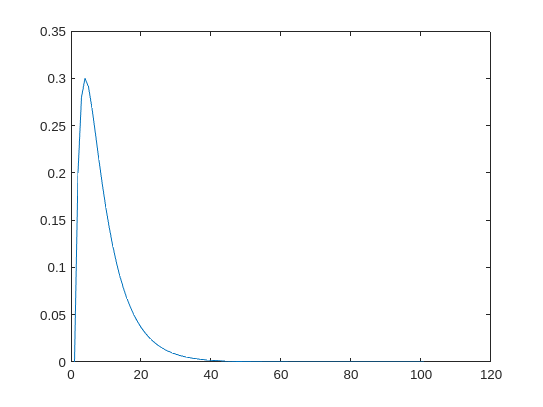

prob = zeros(1, 101);
prob(1, 1) = 0;

x_0 = [1; 0; 0; 0; 0];

for k = 1:100
    x_k = T^k * x_0;
    prob(1, k+1) = x_k(2, 1);
end

plot(1:101, prob)


% Como existe dois estados absorventes e o 2 não é um deles, a probabilidade de estar 
% no estado 2 cresce até um certo ponto e depois começa a descer e a tender
% para 0 quando k -> inf, enquanto que a soma das probabilidades de estar num dos
% estados absorventes tende para 1.

**(c)** Faça um gráfico com a probabilidade de, começando no estado 1, estar no estado 3 ao fim de n passos. Na mesma figura, faça um segundo gráfico com a probabilidade de, começando no estado 1, estar no estado 5 ao fim de n passos. Em ambos os casos, considere n a variar de 1 até 100.

Justifique o que observa.

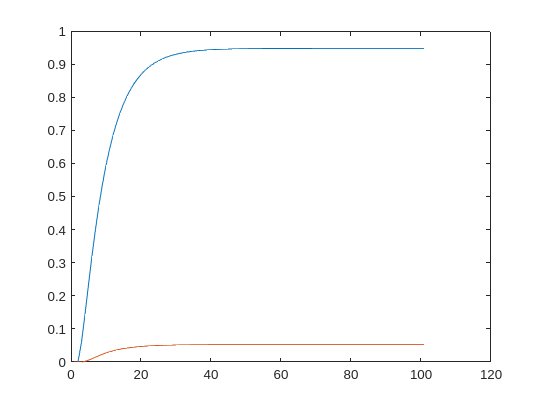

prob = zeros(2, 101);
prob(:, 1) = [0; 0];

x_0 = [1; 0; 0; 0; 0];

for k = 1:100
    x_k = T^k * x_0;
    prob(1, k+1) = x_k(3, 1);
    prob(2, k+1) = x_k(5, 1);
end

plot(1:101, prob)


% Tanto 5 como 3 são estados absorventes, no entanto um deles tem maior
% probabilidade de ser o estado final do que o outro.

**(d) **Determine a matriz Q.

%      1  2  4  3  5 
aux = [8  0  3  0  0; % <-- 1
       2  6  2  0  0; % <-- 2
       0  1  4  0  0; % <-- 4
       0  3  0  10 0; % <-- 3
       0  0  1  0  10]/10; % <-- 5

Q = aux(1:3, 1:3)

Q =     0.8000         0    0.3000
    0.2000    0.6000    0.2000
         0    0.1000    0.4000


**(e)** Determine a matriz fundamental F.

% F = (i - Q)^(-1)
F = inv((eye(length(Q)) - Q))

F =     5.7895    0.7895    3.1579
    3.1579    3.1579    2.6316
    0.5263    0.5263    2.1053


**(f)** Qual a média (valor esperado) do número de passos antes da absorção começando no estado 1? E

começando no estado 2? E se começando no estado 4?

E = sum(F)

E =     9.4737    4.4737    7.8947


**(g)** Começando no estado 1, qual é a probabilidade de absorção do estado 3? E do estado 5? Verifique

a coerência destes valores com o que observou na alínea 6 (c).

R = aux(4:5, 1:3)

R =          0    0.3000         0
         0         0    0.1000



B = R * F

B =     0.9474    0.9474    0.7895
    0.0526    0.0526    0.2105



disp("Probabilidade de absorção do estado 3, começando no estado 1: " + sum(B(1, 1)));

Probabilidade de absorção do estado 3, começando no estado 1: 0.94737


disp("Probabilidade de absorção do estado 5, começando no estado 1: " + sum(B(2, 1)));

Probabilidade de absorção do estado 5, começando no estado 1: 0.052632


**7. Considere o conjunto de páginas Web e respetivas hyperligações entre si dado pelo diagrama seguinte:**

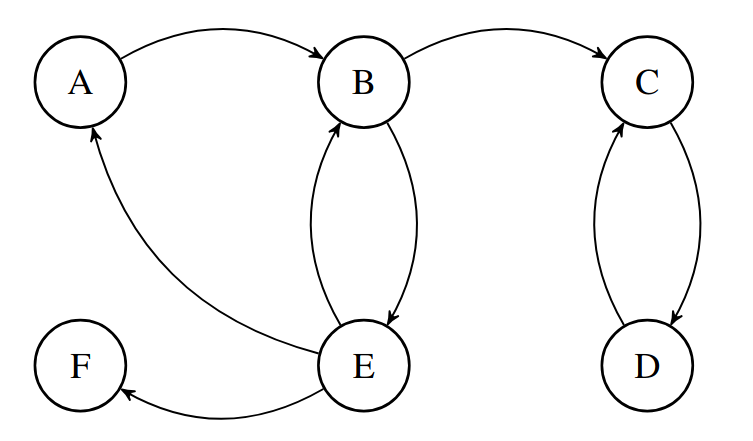

**(a)** Usando a matriz H das hyperligações, obtenha a estimativa do pagerank de cada página ao fim de

10 iterações. Relembre que deve considerar: 

    **(i)** A mesma probabilidade de transição de cada página para todas as páginas seguintes possíveis;

    **(ii)** A probabilidade da página inicial deve ser igual para todas as páginas. 

Qual/quais a(s) página(s) com maior pagerank e qual o seu valor?

%       A   B     C   D   E     F
H = [
        0   0     0   0   1/3   0; % <-- A
        1   0     0   0   1/3   0; % <-- B
        0   1/2   0   1   0     0; % <-- C
        0   0     1   0   0     0; % <-- D
        0   1/2   0   0   0     0; % <-- E
        0   0     0   0   1/3   0; % <-- F
    ]

H =          0         0         0         0    0.3333         0
    1.0000         0         0         0    0.3333         0
         0    0.5000         0    1.0000         0         0
         0         0    1.0000         0         0         0
         0    0.5000         0         0         0         0
         0         0         0         0    0.3333         0



x_0 = ones(length(H), 1)/length(H)

x_0 =     0.1667
    0.1667
    0.1667
    0.1667
    0.1667
    0.1667



for i= 0: 10
    x_0 = H * x_0;
end

pageRank = x_0

pageRank =     0.0009
    0.0021
    0.3321
    0.3315
    0.0017
    0.0009


**(b)** Identifique a ”spider trap” e o ”dead-end” contidos neste conjunto de páginas.

disp("F é um dead-end")

F é um dead-end


disp("C e D é uma spider trap")

C e D é uma spider trap


**(c) **Altere a matriz H para resolver apenas o problema do ”dead-end” e recalcule o pagerank de cada

página novamente em 10 iterações.

%       A   B     C   D   E     F
H = [
        0   0     0   0   1/3   1/6; % <-- A
        1   0     0   0   1/3   1/6; % <-- B
        0   1/2   0   1   0     1/6; % <-- C
        0   0     1   0   0     1/6; % <-- D
        0   1/2   0   0   0     1/6; % <-- E
        0   0     0   0   1/3   1/6; % <-- F
    ]

H =          0         0         0         0    0.3333    0.1667
    1.0000         0         0         0    0.3333    0.1667
         0    0.5000         0    1.0000         0    0.1667
         0         0    1.0000         0         0    0.1667
         0    0.5000         0         0         0    0.1667
         0         0         0         0    0.3333    0.1667




x_0 = ones(length(H), 1)/length(H)

x_0 =     0.1667
    0.1667
    0.1667
    0.1667
    0.1667
    0.1667



for i= 0: 10
    x_0 = H * x_0;
end

pageRank = x_0

pageRank =     0.0050
    0.0116
    0.4865
    0.4832
    0.0088
    0.0050


**(d) **Resolva agora ambos os problemas e recalcule o pagerank de cada página novamente em 10

iterações (assuma β = 0, 8).

beta = 0.8;
A = beta *H + (1-beta)*(ones(6)/6);

A =     0.0333    0.0333    0.0333    0.0333    0.3000    0.1667
    0.8333    0.0333    0.0333    0.0333    0.3000    0.1667
    0.0333    0.4333    0.0333    0.8333    0.0333    0.1667
    0.0333    0.0333    0.8333    0.0333    0.0333    0.1667
    0.0333    0.4333    0.0333    0.0333    0.0333    0.1667
    0.0333    0.0333    0.0333    0.0333    0.3000    0.1667




x_0 = [1/6; 1/6; 1/6; 1/6; 1/6; 1/6];
for i= 0: 10
    x_0 = A * x_0;
end

pageRank = x_0

pageRank =     0.0663
    0.1194
    0.3423
    0.3157
    0.0901
    0.0663


**(e)** Calcule agora o pagerank de cada página considerando um número mínimo de iterações que garanta

que nenhum valor muda mais do que 10^(−4) em 2 iterações consecutivas. Quantos iterações são

necessárias? Compare os valores de pagerank obtidos com os da alínea anterior. O que conclui?

iteracoes = 0;

pageRanks = x_0;

while 1
    x_0 = A * x_0;
    pageRanks(:, iteracoes+2) = x_0;
    exit = 0;
    for i=1:length(pageRanks)
        if abs(pageRanks(i, iteracoes+1) - pageRanks(i, iteracoes+2)) < 10^(-4)
            exit = exit + 1;
        end
    end
    if exit == 6
        break
    end
    iteracoes = iteracoes + 1;
end

x_0

x_0 =     0.0661
    0.1190
    0.3428
    0.3163
    0.0898
    0.0661


disp("O numero minimo de iterações é " + iteracoes)

O numero minimo de iterações é 3
